# Analysis of the connection of two pipes

close all;
clear all;
clc;

%including all parent folders up to the file 'code', this makes visible all
%files within this code
addingPathParentFolderByName('COMSOL_3_pipes_w_100um_rectangular_tetrazine');


#### Parameters

%call to the parameters file
Parameters

#### Length and width per pipe

%Pipe_1
%width
w_1=0;
[var,factor]=getVarTable(w_1,table);
w_1=eval(var{1})*factor
%heigth
height_pipe=0;
[var,factor]=getVarTable(height_pipe,table);
height_pipe=eval(var{1})*factor
%Length
L_1=0;
[var,factor]=getVarTable(L_1,table);
L_1=eval(var{1})*factor

%Pipe_2
%width
w_2=0;
[var,factor]=getVarTable(w_2,table);
w_2=eval(var{1})*factor
%Length
L_2=0;
[var,factor]=getVarTable(L_2,table);
L_2=eval(var{1})*factor
%Angle
varphi_2=0;
[var,factor]=getVarTable(varphi_2,table);
varphi_2=eval(var{1})*factor

%Pipe_3
%width
w_3=0;
[var,factor]=getVarTable(w_3,table);
w_3=eval(var{1})*factor
%Length
L_3=0;
[var,factor]=getVarTable(L_3,table);
L_3=eval(var{1})*factor
%Angle
varphi_3=0;
[var,factor]=getVarTable(varphi_3,table);
varphi_3=eval(var{1})*factor

#### Flow rate for a given pressure drop  

**Description:** This block assumes a syringe is connected to the inlet of the pipe and introduces a constant flow rate Q. The pressure formula follows the Hagen–Poiseuille equation [1, Table 3.1 pp. 43]

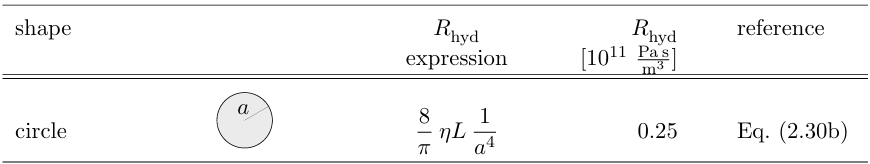

$\Delta P=RQ
$, (1)

where $R$ denotes the pipe resistance and is given as follows

- Rectangular cross-shape $R=\frac{12\mu L}{1-0.63\frac{h}{w}}\cdot\frac{1}{h^3w}$, $w\gg h$

- Circular cross-shape $R=\frac{8\mu L}{\pi r^4}$

where 

$\mu$ is the water viscosity,

$L$ is the channel length,

$r$ is the radius of a circular pipe.

$h$ is the height of a rectangular pipe

$w$ is the width of a rectangular pipe

%resistance of the rectangular Pipe 1
R_1=12*mu_Water*L_1/(1-0.63*height_pipe/w_1)*(1/(height_pipe^3*w_1))

R_1 = 2.4768e+13

%resistance of the rectangular Pipe 2
R_2=12*mu_Water*L_2/(1-0.63*height_pipe/w_2)*(1/(height_pipe^3*w_2))

R_2 = 2.8822e+13

%resistance of the rectangular Pipe 3
R_3=12*mu_Water*L_3/(1-0.63*height_pipe/w_3)*(1/(height_pipe^3*w_3))

R_3 = 3.2905e+13


% Equivalent parallel resistance
Req = 1 / sum(1 ./ [R_1 R_2 R_3])

Req = 9.4822e+12


%evaluating the extra hydraulic resistance
% Specify the MAT file for the parameters
% csvFileName = 'COMSOL_pipe_1_concentration_line_outlet.csv';
csvFileName = 'polygon_outer.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
% preview(csvFileName,opts) %data file preview
table=readtable(csvFileName,opts);
x_pol_outer=table.Var1;
y_pol_outer=table.Var2;

% Specify the MAT file for the parameters
% csvFileName = 'COMSOL_pipe_1_concentration_line_outlet.csv';
csvFileName = 'polygon_upper.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
% preview(csvFileName,opts) %data file preview
table=readtable(csvFileName,opts);
x_pol_upper=table.Var1;
y_pol_upper=table.Var2;

%length of the inlet
L_in_Pipe_1=abs(x_pol_outer(10)-x_pol_upper(1)) %inlet connection to pipe 1

L_in_Pipe_1 = 4.4459e-04

L_in_Pipe_1=abs(x_pol_outer(2)-x_pol_outer(1))/3 %inlet connection to pipe 1

L_in_Pipe_1 = 7.0000e-05

L_in=x_pol_outer(2)-x_pol_outer(1) %inlet connection to Pipes 2 and 3

L_in = 2.1000e-04

%w_in=(abs(y_pol_outer(1)-y_pol_outer(10))+abs(y_pol_upper(1)-y_pol_outer(10)))
w_in=2*abs(y_pol_upper(1)-y_pol_outer(10))

w_in = 3.1072e-04

% w_in=(abs(y_pol_outer(1)-y_pol_outer(10)))
%length of the outlet
L_out=x_pol_outer(5)-x_pol_outer(4)

L_out = 2.1000e-04

w_out=abs(y_pol_outer(6)-y_pol_outer(5))

w_out = 9.8995e-05

%inlet resistance to Pipe 1
R_in_Pipe_1=12*mu_Water*L_in_Pipe_1/(1-0.63*height_pipe/w_in)*(1/(height_pipe^3*w_in))

R_in_Pipe_1 = 2.4017e+10

%inlet resistance to Pipes 2 and 3
R_in=12*mu_Water*L_in/(1-0.63*height_pipe/w_in)*(1/(height_pipe^3*w_in))

R_in = 7.2052e+10

%outlet resistance
R_out=12*mu_Water*L_out/(1-0.63*height_pipe/w_out)*(1/(height_pipe^3*w_out))

R_out = 2.9807e+11



% Total flow to the three pipes
Q_T=p0/Req

Q_T = 6.3277e-11

Q_T_uL_min=Q_T*6e10

Q_T_uL_min = 3.7966


%Flow to the pipe 1 in a single connection
Q_1=p0/(Req)*Req/R_1;
Q_1_uL_min=Q_1*6e10

Q_1_uL_min = 1.4535



%Flow to the pipe 2 in a single connection
Q_2=p0/(R_in+R_out+Req)*Req/R_2;
Q_2_uL_min=Q_2*6e10

Q_2_uL_min = 1.2021



%Flow to the pipe 2 in a single connection
Q_3=p0/(R_in+R_out+Req)*Req/R_3;
Q_3_uL_min=Q_3*6e10

Q_3_uL_min = 1.0530

## 3D Pipe 1, 2, 3

### COMSOL simulation

%Pipe 1
% Specify the MAT file for the parameters
% csvFileName = 'COMSOL_pipe_1_concentration_line_outlet.csv';
csvFileName = '3D_Pipe_1_Outlet_Concentration_Surface_Average.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
% preview(csvFileName,opts) %data file preview
table=readtable(csvFileName,opts);
time=table.Var1;
%concentration
conc_Pipe_1_COMSOL=table.Var2;
%CIR
h_cir_1_COMSOL=gradient(conc_Pipe_1_COMSOL,time);

%Pipe 2
% Specify the MAT file for the parameters
% csvFileName = 'COMSOL_pipe_1_concentration_line_outlet.csv';
csvFileName = '3D_Pipe_2_Outlet_Concentration_Surface_Average.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
% preview(csvFileName,opts) %data file preview
table=readtable(csvFileName,opts);
time=table.Var1;
%concentration
conc_Pipe_2_COMSOL=table.Var2;
%CIR
h_cir_2_COMSOL=gradient(conc_Pipe_2_COMSOL,time);

%Pipe 3
% Specify the MAT file for the parameters
% csvFileName = 'COMSOL_pipe_1_concentration_line_outlet.csv';
csvFileName = '3D_Pipe_3_Outlet_Concentration_Surface_Average.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
% preview(csvFileName,opts) %data file preview
table=readtable(csvFileName,opts);
time=table.Var1;
%concentration
conc_Pipe_3_COMSOL=table.Var2;
%CIR
h_cir_3_COMSOL=gradient(conc_Pipe_3_COMSOL,time);


### Theoretical calculations

%Pipe 1
%mean velocity
%Rectangular channel of size w x h [1, below Eq. (3.40) pag. 53]
v_char=Q_1/(w_1*height_pipe)

v_char = 0.0043


%Peclet number, see [3, Eq. below 11] 
Pe=v_char*height_pipe/D_coeff;

%Evaluating the Effective Diffusion coefficient
%Shallow rectangular channel, h<<w, see the constant 1/200 in [3,
%Eq. (15)] and the formula for the diffusion coeff in [3, Eq. (1)].
D_eff=D_coeff*(1+1/200*Pe^2);

%Evaluating the concentration of the straigth channel
conc_Pipe_1_Theo=1./2.*erfc((L_1-v_char*time)./(2*sqrt(D_eff*time)));
% %Evaluating the channel impulse response
h_cir_1_Theo=gradient(conc_Pipe_1_Theo,time);

%finding the maximum
tau_1=L_1/v_char-2*D_eff/v_char^2;
[~,idx]=min(abs(time-tau_1));
peak_1=h_cir_1_Theo(idx);

%Pipe 2
%mean velocity
%Rectangular channel of size w x h [1, below Eq. (3.40) pag. 53]
v_char=Q_2/(w_2*height_pipe)

v_char = 0.0030

%Peclet number, see [3, Eq. below 11] 
Pe=v_char*height_pipe/D_coeff;
%Evaluating the Effective Diffusion coefficient
%Shallow rectangular channel, h<<w, see the constant 1/200 in [3,
%Eq. (15)] and the formula for the diffusion coeff in [3, Eq. (1)].
D_eff=D_coeff*(1+1/200*Pe^2);

%Matlab code to evaluate the integral
syms t x rd v varphi D C_0 w
% Define the substitution for x
z = (x - v*t + varphi*rd) / (2*sqrt(D*t));
% Define the integrand
integrand = 1/2*C_0*erfc(z);
% Perform the symbolic integration from r = 0 to r = dr
I = simplify(1/(w)*int(integrand, rd, 0, w));
%Performing the integral
c_avg=1/(w)*int(integrand,rd);
%evaluating the integral limits between rd=0 and rd=2r
c_avg_int=subs(c_avg,[rd,C_0],[w,1])-subs(c_avg,[rd,C_0],[0,1]);
c_avg_param_int_Pipe_2=subs(c_avg_int,[x,D,v,w,varphi],[L_2,D_eff,v_char,w_2,varphi_2]);
conc_Pipe_2_Theo=double(subs(c_avg_param_int_Pipe_2,[t],[time(2:end)]));

%Evaluating the concentration of the straigth channel
% conc_Pipe_2_Theo=1./2.*erfc((L_2-v_char*time)./(2*sqrt(D_eff*time)));
% %Evaluating the channel impulse response
h_cir_2_Theo=gradient(conc_Pipe_2_Theo,time(2:end));
%finding the maximum
tau_2=L_2/v_char-2*D_eff/v_char^2;
[~,idx]=min(abs(time-tau_2));
peak_2=h_cir_2_Theo(idx);

%Pipe 3
%mean velocity
%Rectangular channel of size w x h [1, below Eq. (3.40) pag. 53]
v_char=Q_3/(w_3*height_pipe)

v_char = 0.0025


%Peclet number, see [3, Eq. below 11] 
Pe=v_char*height_pipe/D_coeff;

%Evaluating the Effective Diffusion coefficient
%Shallow rectangular channel, h<<w, see the constant 1/200 in [3,
%Eq. (15)] and the formula for the diffusion coeff in [3, Eq. (1)].
D_eff=D_coeff*(1+1/200*Pe^2);

%Matlab code to evaluate the integral
syms t x rd v varphi D C_0 w
% Define the substitution for x
z = (x - v*t + varphi*rd) / (2*sqrt(D*t));
% Define the integrand
integrand = 1/2*C_0*erfc(z);
% Perform the symbolic integration from r = 0 to r = dr
I = simplify(1/(w)*int(integrand, rd, 0, w));
%Performing the integral
c_avg=1/(w)*int(integrand,rd);
%evaluating the integral limits between rd=0 and rd=2r
c_avg_int=subs(c_avg,[rd,C_0],[w,1])-subs(c_avg,[rd,C_0],[0,1]);
c_avg_param_int_Pipe_3=subs(c_avg_int,[x,D,v,w,varphi],[L_3,D_eff,v_char,w_3,varphi_3]);
conc_Pipe_3_Theo=double(subs(c_avg_param_int_Pipe_3,[t],[time(2:end)]));

% %Evaluating the concentration of the straigth channel
% conc_Pipe_3_Theo=1./2.*erfc((L_3-v_char*time)./(2*sqrt(D_eff*time)));
% %Evaluating the channel impulse response
h_cir_3_Theo=gradient(conc_Pipe_3_Theo,time(2:end));

%finding the maximum
tau_3=L_3/v_char-2*D_eff/v_char^2;
[~,idx]=min(abs(time-tau_3));
peak_3=h_cir_3_Theo(idx);

### Plots

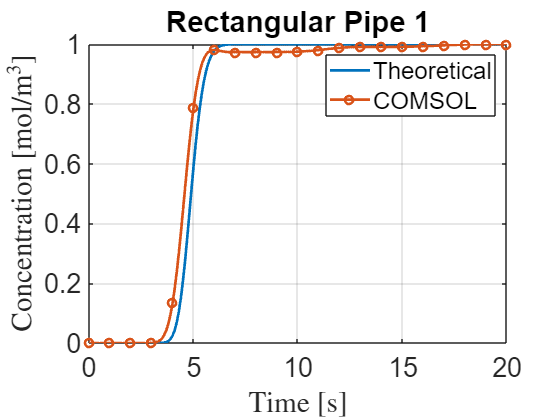

%Pipe 1
figure;
plot(time,conc_Pipe_1_Theo,'LineWidth',2); grid on; hold on;
plot(time,conc_Pipe_1_COMSOL,'-o','LineWidth',2,'MarkerIndices',1:10:length(conc_Pipe_1_COMSOL)); grid on;
xlabel("Time [s]",'Interpreter','latex');
ylabel("Concentration [mol/m$^3$]",'Interpreter','latex');
title("Rectangular Pipe 1")
legend({'Theoretical','COMSOL'},'Location','northeast');
set(gca,'FontSize',fontsize);

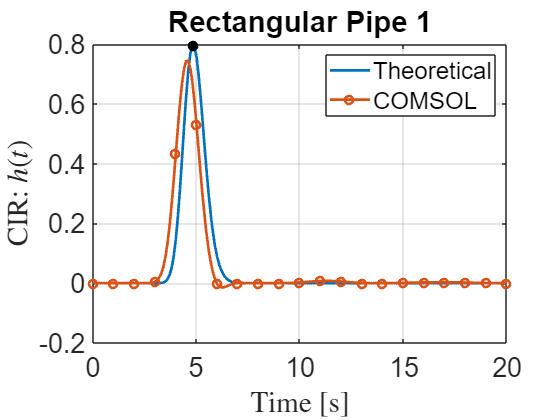


figure;
plot(time,h_cir_1_Theo,'LineWidth',2); grid on; hold on;
plot(time,h_cir_1_COMSOL,'-o','LineWidth',2,'MarkerIndices',1:10:length(conc_Pipe_1_COMSOL));
plot(tau_1,peak_1,'o','LineWidth',2,'Color','black',MarkerFaceColor='black');
xlabel("Time [s]",'Interpreter','latex');
ylabel("CIR: $h(t)$",'Interpreter','latex');
title("Rectangular Pipe 1")
set(gca,'FontSize',fontsize);
legend({'Theoretical','COMSOL'},'Location','northeast');

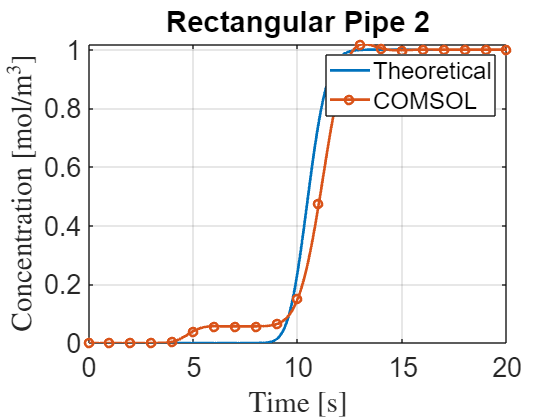


%Pipe 2
figure;
plot(time(2:end),conc_Pipe_2_Theo,'LineWidth',2); grid on; hold on;
plot(time,conc_Pipe_2_COMSOL,'-o','LineWidth',2,'MarkerIndices',1:10:length(conc_Pipe_1_COMSOL)); grid on;
xlabel("Time [s]",'Interpreter','latex');
ylabel("Concentration [mol/m$^3$]",'Interpreter','latex');
title("Rectangular Pipe 2")
legend({'Theoretical','COMSOL'},'Location','northeast');
set(gca,'FontSize',fontsize);

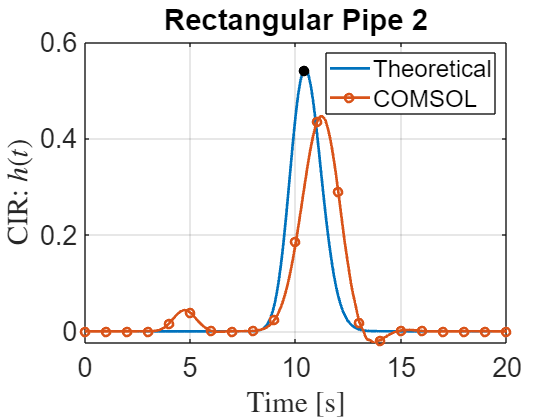


figure;
plot(time(2:end),h_cir_2_Theo,'LineWidth',2); grid on; hold on;
plot(time,h_cir_2_COMSOL,'-o','LineWidth',2,'MarkerIndices',1:10:length(conc_Pipe_1_COMSOL));
plot(tau_2,peak_2,'o','LineWidth',2,'Color','black',MarkerFaceColor='black');
xlabel("Time [s]",'Interpreter','latex');
ylabel("CIR: $h(t)$",'Interpreter','latex');
title("Rectangular Pipe 2")
set(gca,'FontSize',fontsize);
legend({'Theoretical','COMSOL'},'Location','northeast');

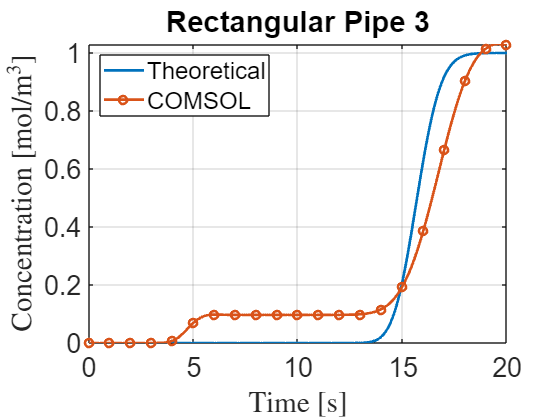


%Pipe 3
figure;
plot(time(2:end),conc_Pipe_3_Theo,'LineWidth',2); grid on; hold on;
plot(time,conc_Pipe_3_COMSOL,'-o','LineWidth',2,'MarkerIndices',1:10:length(conc_Pipe_1_COMSOL)); grid on;
xlabel("Time [s]",'Interpreter','latex');
ylabel("Concentration [mol/m$^3$]",'Interpreter','latex');
title("Rectangular Pipe 3")
legend({'Theoretical','COMSOL'},'Location','northwest');
set(gca,'FontSize',fontsize);

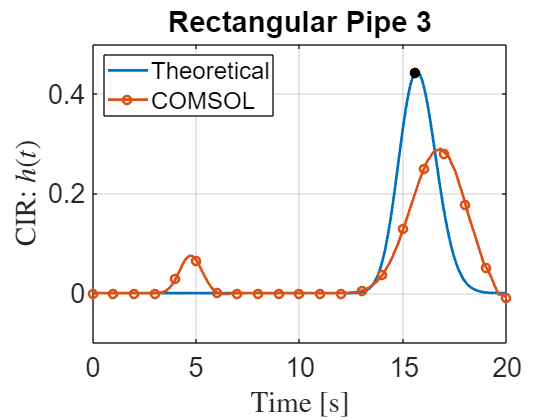


figure;
plot(time(2:end),h_cir_3_Theo,'LineWidth',2); grid on; hold on;
plot(time,h_cir_3_COMSOL,'-o','LineWidth',2,'MarkerIndices',1:10:length(conc_Pipe_1_COMSOL));
plot(tau_3,peak_3,'o','LineWidth',2,'Color','black',MarkerFaceColor='black');
xlabel("Time [s]",'Interpreter','latex');
ylabel("CIR: $h(t)$",'Interpreter','latex');
title("Rectangular Pipe 3")
set(gca,'FontSize',fontsize);
legend({'Theoretical','COMSOL'},'Location','northwest');

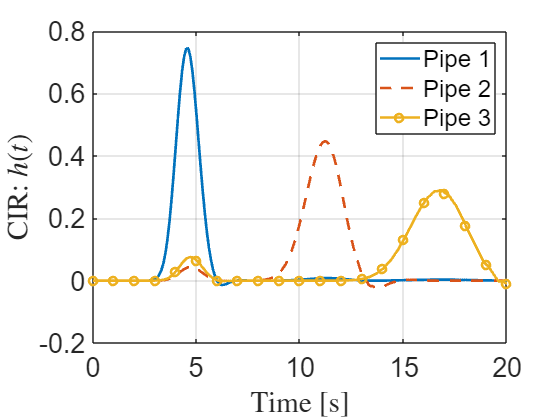


figure;
plot(time,h_cir_1_COMSOL,'-','LineWidth',2,'MarkerIndices',1:10:length(conc_Pipe_1_COMSOL));grid on; hold on;
plot(time,h_cir_2_COMSOL,'--','LineWidth',2,'MarkerIndices',1:10:length(conc_Pipe_1_COMSOL));
plot(time,h_cir_3_COMSOL,'-o','LineWidth',2,'MarkerIndices',1:10:length(conc_Pipe_1_COMSOL));
xlabel("Time [s]",'Interpreter','latex');
ylabel("CIR: $h(t)$",'Interpreter','latex');
set(gca,'FontSize',fontsize);
legend({'Pipe 1','Pipe 2','Pipe 3'},'Location','northeast');

function addingPathParentFolderByName(targetName)
    % Start from the current directory
    currFolder = pwd;
    found = false;
    
    % Continue searching until you reach the root folder
    while true
        % Get the parent folder
        [parentFolder, currentName] = fileparts(currFolder);
        
        % Check if the current folder's name is the target
        if strcmpi(currentName, targetName)
            found = true;
            break;
        end
        
        % If we've reached the root or no change, exit the loop
        if isempty(parentFolder) || strcmp(currFolder, parentFolder)
            break;
        end
        
        % Move one level up
        currFolder = parentFolder;
    end

    if found
        addpath(genpath(currFolder));
        fprintf('Adding matlab path to: %s\n', currFolder);
    else
        error('Folder named "%s" not found in any parent directory.', targetName);
    end
end

function [value,factor]= getVarTable(var,table)
%This function extract the value of the variable specified in the entry var within
%the table specified in entry table

varName = inputname(1);

%find the corresponding entry within the table of parameters
for i=1:numel(table(:,1))
    entry_str=strcmp(table{i,1},varName);
    if entry_str
        entry_table=i;
        break
    end
end

%validating
if isempty(entry_table)
    error('Table has no column named "%s".', varName);
    value=NaN;
    factor=NaN;
else
    %reading the value in the second column of the table
    str=table{entry_table,2};
    if(isempty(findstr(str{1},'[')))
        value=table{entry_table,2};
    else
        value=extractBefore(table{entry_table,2},'[');
    end
    %reading the units of the value within the second column in the table
    unit = extractBetween(table{entry_table,2}, "[", "]"); % e.g. ["um"; "mm"; "nm"; "m"]
    if isempty(unit)
        factor=1;
    else
        %Define your conversion map to meters
        convMap = containers.Map( ...
            {'nm','um','mm','cm','m','km','rad','s','ms','us','ns','Pa','mmHg','m/s','mol/m^3','mol/L','m^2/s','cm^2/s','g/mol'}, ...
            [1e-9,1e-6,1e-3,1e-2,1,1e3,1,1,1e-3,1e-6,1e-9,1,133.322,1,1,1e3,1,1e-4,1e-3] );
        %Finding the conversion factors
        if isKey(convMap, unit)
            factor = convMap(unit{1});
        else
            error('Unit "%s" not recognized.', unit{1});
        end
    end

end
end

function varName = getVarName(var)
%This function extract the value of the variable specified in var within
%the table specified in table

% getVarName   Extract the name of the workspace variable
varName = inputname(1);
end


## References

[1] H. Bruus, *Theoretical Microfluidics*. 2008. doi: [10.1093/oso/9780199235087.001.0001](https://doi.org/10.1093/oso/9780199235087.001.0001).  

[2] Howard C. Berg. 1993. Random Walks in Biology. Princeton University Press.

[3] M. L. Parks and L. A. Romero, “Taylor–Aris dispersion in high aspect ratio columns of nearly rectangular cross section,” *Mathematical and Computer Modelling*, vol. 46, no. 5, pp. 699–717, Sep. 2007, doi: [10.1016/j.mcm.2006.11.029](https://doi.org/10.1016/j.mcm.2006.11.029).  